Autorzy: Krzysztof S, Hubert K

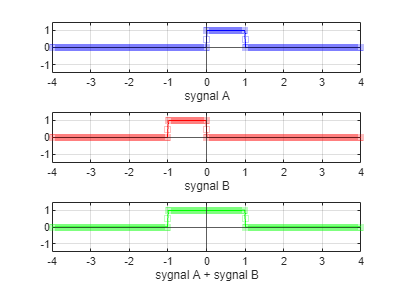

clc; clear; close all;

% dziedzina wykresu
cz_probkowania = 1 /100;  %to sie chyba nazywa czestotliwosc probkowania xd

% komentarz do powyższego: W tym konkretnym wypadku mamy doczynienia z
% okresem co jaki wykonujemy pobranie próbki
% sygnału, wraz ze zwiększaniem tej wartości
% częstotliwość próbkowania maleje (czestotliwosc = 1/okres)
% zjawisko jest widoczne na wykresie po poruszaniu suwakiem,
% liczba punktów maleje im większa wartość zmiennej
% (najbardziej widoczne dla przedziału (1, 1/10)
% Hubert



% Kontrolki od sygnału A

amplituda_A =1; %default = 1
opoznienie_A =0.5; %default = 0.5
wydluzenie_A =1; %default = 1 

% Kontrolki od sygnału B

amplituda_B = 1; %default = 1
opoznienie_B = -0.5; %default = -0.5
wydluzenie_B = 1; %default = 1


%wykres view setup (granice okienka)
l_krawedz = -4; 
p_krawedz = 4;
g_krawedz = max([amplituda_A, amplituda_B]) + 0.5;
d_krawedz = min([g_krawedz * -1, amplituda_A - 0.5, amplituda_B - 0.5]);

t = l_krawedz : cz_probkowania : p_krawedz; %zeby program wiedzial zakres dziedziny

subplot(3,1,1) %3 rzedy, 1 kolumna, wykres 1
    x1 = xpi(t, amplituda_A, opoznienie_A, wydluzenie_A); 
    % amplituda * PI((t - opoznienie) / wydluzenie)
    
        %wykresu rysowanko
        plot(t, x1, 'b-square'); grid on;
        xline(0);
        yline(0);
        xlim([l_krawedz p_krawedz])
        ylim([d_krawedz g_krawedz])
        xlabel('sygnal A')

subplot(3,1,2) %3 rzedy, 1 kolumna, wykres 2
    amplituda = 1; %default = 1
    opoznienie = -1/2; %default = 0
    wydluzenie = 1; %default = 1
    
    x2 = xpi(t, amplituda_B, opoznienie_B, wydluzenie_B); 
    % amplituda * PI((t - opoznienie) / wydluzenie)
    
        %wykresu rysowanko
        plot(t, x2, 'r-square'); grid on;
        xline(0);
        yline(0);
        xlim([l_krawedz p_krawedz])
        ylim([d_krawedz g_krawedz])
        xlabel('sygnal B')

subplot(3,1,3) %3 rzedy, 1 kolumna, wykres 3
    
    %dzialanie jakie chcemy wykonac tu (mnozenie -> .* !!)
    x3 = x1+x2;
   
        %wykresu rysowanko
        plot(t, x3, 'g-square'); grid on;
        xline(0);
        yline(0);
        xlim([l_krawedz p_krawedz])
        ylim([d_krawedz g_krawedz])
        xlabel('sygnal A + sygnal B')